Caricamento Immagine

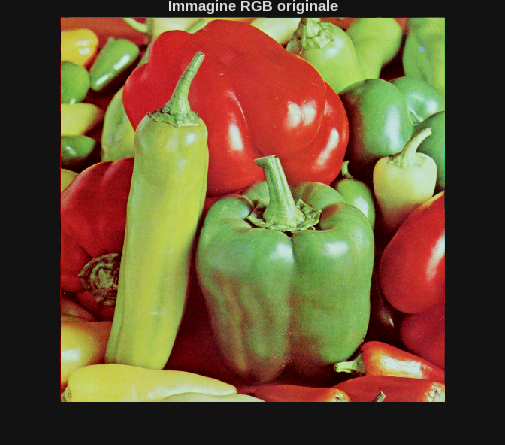

rgbOriginale = imread("imgs/peppers.png");
figure;
imshow(rgbOriginale)
title("Immagine RGB originale");

RgbOriginaleDouble = im2double(rgbOriginale); %Imagine con valori 0-1

RGB --> HSV usando la funzione rgb2hsv. Tonalità (H), Saturazione (S), Valore(V)

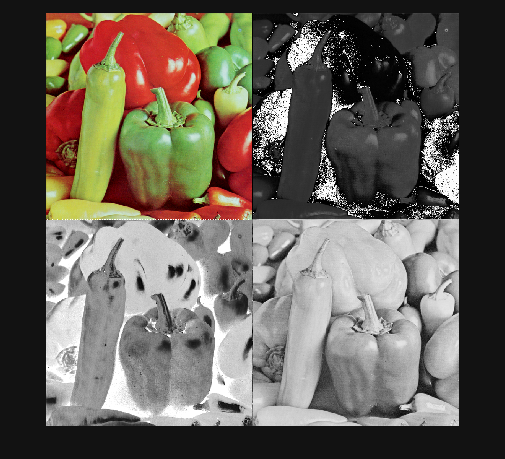

imgHsv = rgb2hsv(rgbOriginale);
figure;
montage({rgbOriginale,imgHsv(:,:,1),imgHsv(:,:,2),imgHsv(:,:,3)})

RGB --> YUV usando la funzione gb2ycbcr. Luminanza(Y), Crominanza Blu (Cb/U), Crominanza Rosso (Cr/V).

Possiamo anche "convertire a mano" usando dei valori standard, i quali vanno moltiplicati per l'immagine RGB.

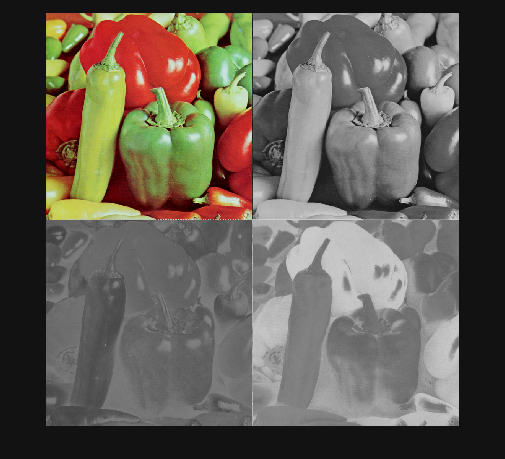

imgYuv = rgb2ycbcr(rgbOriginale);
montage({rgbOriginale,imgYuv(:,:,1),imgYuv(:,:,2),imgYuv(:,:,3)})

Possiamo anche "convertire a mano" usando dei valori standard, i quali vanno moltiplicati per l'immagine RGB.

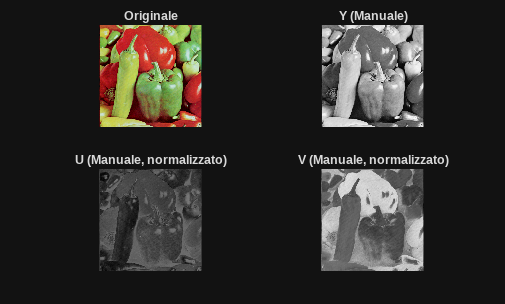

function yuv_img = my_rgb2yuv(rgb_img)  
    % Estraiamo i canali R, G, B
    R = rgb_img(:,:,1);
    G = rgb_img(:,:,2);
    B = rgb_img(:,:,3);
    
    % Matrice di conversione standard (BT.601)    
    Y = 0.299*R + 0.587*G + 0.114*B;
    U = -0.14713*R - 0.28886*G + 0.436*B;
    V = 0.615*R - 0.51499*G - 0.10001*B;
    
    % Combiniamo i canali.
    yuv_img = cat(3, Y, U, V);
end

imgYuvMan = my_rgb2yuv(RgbOriginaleDouble);
figure;
subplot(2, 2, 1); imshow(rgbOriginale); title('Originale');
subplot(2, 2, 2); imshow(imgYuvMan(:,:,1),[]); title('Y (Manuale)');
subplot(2, 2, 3); imshow(imgYuvMan(:,:,2),[]); title('U (Manuale, normalizzato)');
subplot(2, 2, 4); imshow(imgYuvMan(:,:,3),[]); title('V (Manuale, normalizzato)');

RGB --> CMY (Cyan,Magenta,Yellow). Modello sottrattivo, usato nella stampa.

La formula è C = 1-R, M = 1-G, Y=1-B.

(Conviene usare l'immagine double, per precisione).

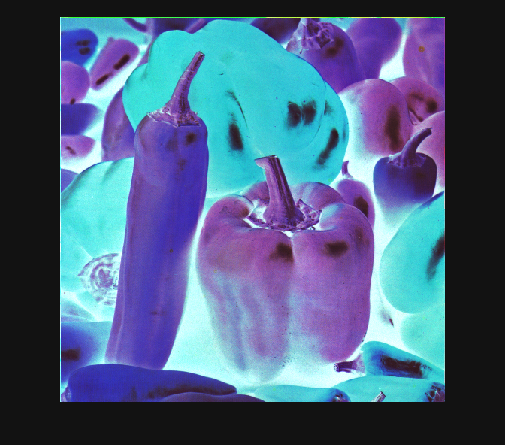

imgCmy = 1 - RgbOriginaleDouble;
figure;
imshow(imgCmy);